# Oskar Chrostowski

# Sprawdzian 1. 

**Zad. 1.** Plik `dane.dat` zawiera zmierzone wartości położenia w czasie. 

- Wczytaj ten plik. 

- Sporządź wykres surowych danych zaznaczając je tylko kółkami.

- Spróbuj dopasować dane wielomianami różnego stopnia, by okreslić jaki to rodzaj ruchu.

- Dodaj do wykresu krzywą najlepszego dopasowania. Umieść jej równanie na wykresie.

- Opisz odpowiednio wykres.  

- Zapisz wykres do pliku .png.

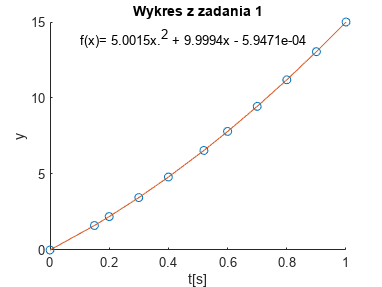

clear all
close all
%podpunkt 1
dane = importdata("dane.dat");

%podpunk 2
x = dane(:,1);
y = dane(:,2);
%plot(x,y,"o")

%podpunk 3
p1 = polyfit(x,y,1); %wielomian 1 stopnia
f1 = polyval(p1,x);

p2 = polyfit(x,y,2); %wielomian 2 stopnia
f2 = polyval(p2,x);

p3 = polyfit(x,y,3); %wielomian 3 stopnia
f3 = polyval(p3,x);


hold on
plot(x,y,'o') %przeniesiony plot z podpunktu drugiego
%plot(x,f1)
plot(x,f2) %moim zdaniem parzyste stopnie wielomianu najlepiej dopasowują się do punktów
%plot(x,f3) 

%podpunkt 5
xlabel("t[s]")
ylabel("y")
title("Wykres z zadania 1")
text(0.1,14,"f(x)= 5.0015x.^2 + 9.9994x - 5.9471e-04") %podpunkt 4
hold off

%podpunkt 6
saveas(gcf,"aproksymacja.png")

**Zad. 2**. Pewna funkcja ma postać:


$$F(\Omega) = H(\Omega)e^{j\theta(\Omega)}, \:\:\; \Omega \ge 0$$


Gdzie:


$$H(\Omega) = \frac{1}{\sqrt{(1-\Omega^2)^2 +(2\zeta\Omega)^2}}$$



$$\theta(\Omega)=\mathrm{arctg}\frac{2\zeta\Omega}{1-\Omega^2$$


i $\zeta < 1$.

- Wygeneruj 200 wartości $\Omega$ z zakresu 0.1 do 10 funkcją `logspace()`. Przyjmij $\zeta = 0.05$.

- Na jednym wykresie nanieś $H(\Omega)$ i $\theta(\Omega)$. Do obliczenia $\theta(\Omega)$ skorzystaj z funkcji `atan2()` i przelicz otrzymane kąty z radianów na stopnie. Funkcje mają mieć osobne osi $y$: logarytmiczną dla $H(\Omega)$ i liniową dla $\theta(\Omega)$. Oś $x$ ma być logarytmiczna.   

clear all
close all
%podpunkt 1
omega = logspace(0.1,10,200);
c=0.05;
%podpunkt 2
H = 1./sqrt((1-omega.^2).^2 + (2.*c.*omega).^2)

H =     1.6714    0.9971    0.6603    0.4633    0.3368    0.2507    0.1897    0.1452    0.1122    0.0872    0.0682    0.0535    0.0421    0.0332    0.0262    0.0207    0.0164    0.0130    0.0103    0.0082    0.0065    0.0052    0.0041    0.0033    0.0026    0.0021    0.0016    0.0013    0.0010    0.0008    0.0007    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


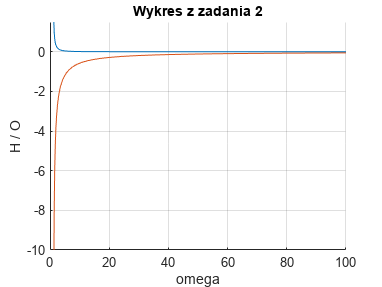

O = rad2deg(atan2((2.*c.*omega)./(1-omega.^2),1)); %zamiania radianów na stopnie za pomocą rad2deg
hold on
loglog(omega,H)
semilogx(omega,O)
title("Wykres z zadania 2")
xlabel("omega")
ylabel("H / O")
axis([0 100 -10 1.5]) %limit, w celu lepszego spojrzenia na wykres
grid on %siatka
hold off